Show how we can add together several shorter exposures -- even with camera motion -- to simulate a single longer exposure

First, set up a default scenario

ieInit;
useScene = sceneMap("Cornell Box"); % Select desired scene
useScenario = ivScenario(useScene);

% ivScenario has defaults, but we can over-ride them
useScenario.exposureTime = 0.01;% in seconds
useScenario.clipLength = 0.05;% Long Exposure
useScenario.raysPerPixel = 1024;
useScenario.fastPreview = 4;% divide rays & rez for previewing

% Save short exposure for later use
shortExposure = useScenario.exposureTime;

% calculate how many frames we need to add together
numFrames = round(useScenario.clipLength / useScenario.exposureTime);

Now we can modify settings or accept the default, and then create our video clips

sceneVideoClip(useScenario); % multi-capture

[INFO]: Read 7 materials and 0 textures.
[INFO]: Attribute processing: 
[INFO]: Identified 5 assets; parsed up to line 46
Film diagonal not used for pinhole and human eye
Film diagonal not used for pinhole and human eye
Elapsed time is 0.068254 seconds.
[INFO]: Uploading data:
[INFO]: Sent 1,226 bytes  received 167 bytes  2,786.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-gpu-djc12661 sh -c " pbrt  --gpu  --outfile /home/david81/ISETRemoteRender/cornell_box/renderings/cornell_box.exr /home/david81/ISETRemoteRender/cornell_box/cornell_box.pbrt "
[INFO]: Rendered remotely in: 69.03 sec
[INFO]: Downloading data:
[INFO]: Sent 46 bytes  received 10,895,691 bytes  4,358,294.80 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/cornell_box.exr
Elapsed time is 0.071482 seconds.
[INFO]: Uploading data:
[INFO]: Sent 1,220 bytes  received 167 bytes  924.67 bytes/sec
[INFO]: Data uploaded successfu

% Single (longer) capture
useScenario.exposureTime = useScenario.clipLength;
sceneVideoClip(useScenario);

[INFO]: Read 7 materials and 0 textures.
[INFO]: Attribute processing: 
[INFO]: Identified 5 assets; parsed up to line 46
Film diagonal not used for pinhole and human eye
Film diagonal not used for pinhole and human eye
Elapsed time is 0.063069 seconds.
[INFO]: Uploading data:
[INFO]: Sent 1,227 bytes  received 167 bytes  2,788.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-gpu-djc12661 sh -c " pbrt  --gpu  --outfile /home/david81/ISETRemoteRender/cornell_box/renderings/cornell_box.exr /home/david81/ISETRemoteRender/cornell_box/cornell_box.pbrt "
[INFO]: Rendered remotely in: 69.21 sec
[INFO]: Downloading data:
[INFO]: Sent 46 bytes  received 12,012,783 bytes  8,008,552.67 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/cornell_box.exr
Local cpCam ran  in: 28.86 seconds of CPU time.
Total cpCam ran  in: 80.0858 total seconds.


By default, results are in local/synthetic-scene-tests, labeled with their exposure time in ms,  and the frame number in the multi-frame sequence.

We call sceneSynthesize both on the multiple exposures to sum them up,  and on the longer exposure(s) which we want to compare. 

We do this even for the case of a single longer exposure because it also does some baseline processing of the raw scene.

Typically the "start" frame is 001, so we've currently hard-coded that.

sceneSynthesize(fullfile(ivDirGet('computed'), ...
    sprintf('%s*-%03d.exr', useScene, round(shortExposure * 1000))),numFrames);
sceneSynthesize(fullfile(ivDirGet('computed'), ...
    sprintf('%s*-%03d.exr', useScene, round(useScenario.clipLength * 1000))),1);

NOTE: We need to move the generated files to generated, or put them there right away:)

Now we can compare the synthesized scene(s).

sceneHomeDir =  ivDirGet('computed');
% scene names have 3 codes:
% * exposureTime in ms
% * first frame in series (typically 001)
% * last frame in series (typically 001 or numFrames)
[sensorSingle, sensorMulti] = sceneCompare( ...
    fullfile(sceneHomeDir,sprintf('%s-%03d-%03d-%03d.mat',useScene, ...
        round(shortExposure*1000), 1, numFrames)), ...
    fullfile(sceneHomeDir, sprintf('%s-%03d-%03d-%03d.mat',useScene, ...
        round(useScenario.exposureTime*1000),1,1)), useScenario.exposureTime);

Denoised in: 21.749
Denoised in: 20.858


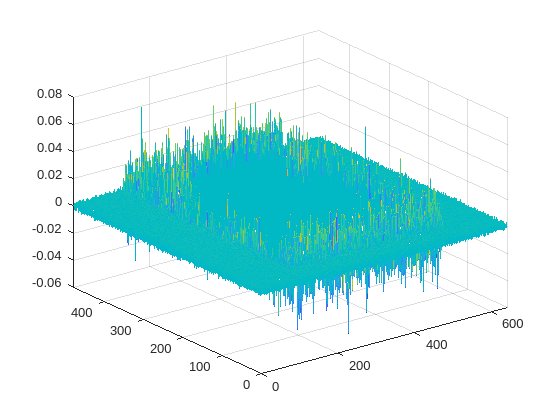

% Show results
mesh(sensorSingle.data.volts - sensorMulti.data.volts);

[ssimVal, ssimMap] = ssim(sensorSingle.data.volts, sensorMulti.data.volts);
fprintf('%f\n',ssimVal)

0.997677


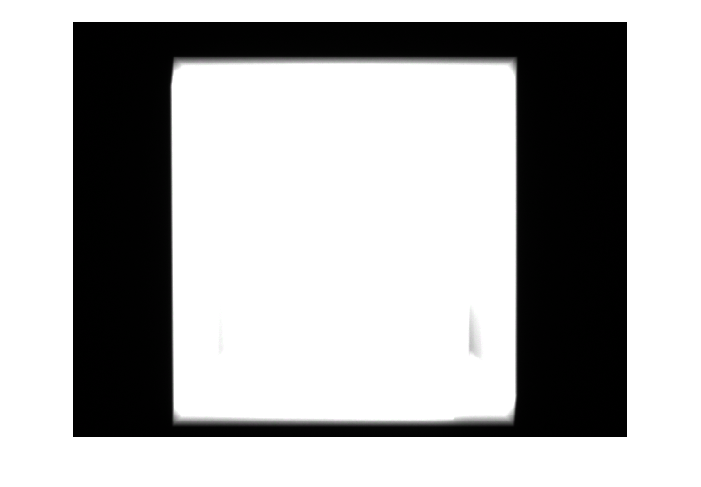

imshowpair(sensorSingle.data.volts,sensorMulti.data.volts,'falsecolor');

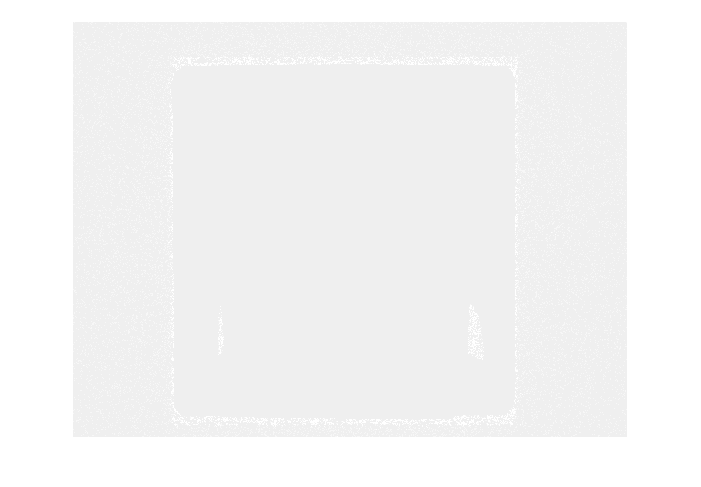

imshow(histeq(sensorSingle.data.volts - sensorMulti.data.volts));

function useScene = sceneMap(sceneLabel)
switch sceneLabel
    case 'Pavilion-Day'
        useScene = 'pavilion-day';
    case 'Paviioon-Night'
        useScene = 'pavilion-night';
    case "MacBeth Checker"
        useScene = 'MacBethChecker';
    case "Cornell Box"
        useScene = 'cornell_box';
end
end